%Here we fire on the four regions signal, see the firing rates as well, dn
%generate the image that is used in fig3 of the paper


% Suppose fd and td are already defined in your workspace

load('four_regions.mat', 'fd', 'td'); % Load the existing signal vector and time vector
disp('Loaded existing signal vector from generated_signal.mat');

Loaded existing signal vector from generated_signal.mat



alpha = 0.70;
kappa = 2450;
Fm = 50;
BW = 2*pi*Fm;
c1 = 1;
shift = 3 * c1;

[tn, time_stamps, f_n, loc, NoF] = sampling_running_func(fd, td, alpha, kappa, Fm, c1, shift);

disp(['Number of Firings: ', num2str(NoF)]);

Number of Firings: 95


NoF=length(time_stamps)-1;

iter=25;
F_est = reconstruction_running_func(NoF, td, f_n-shift, time_stamps, loc, tn, BW, Fm, iter);%%


10 * log10( norm(fd(50000:end-50000) - F_est(50000:end-50000,iter))^2 / norm(fd(50000:end-50000)).^2 )

ans = -52.2386

disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 25]


disp(['iter: ', num2str(iter)]);

iter: 25


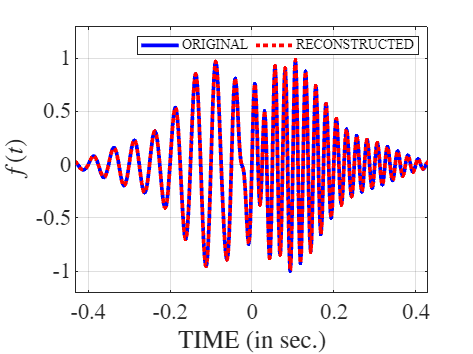





figure;
plot(td, (fd)/c1, 'b', 'DisplayName', 'ORIGINAL', 'LineWidth', 3); hold on;
plot(td, F_est(:,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED', 'LineWidth', 3); 

xlabel('TIME (in sec.)','FontSize',18,'FontName','Times','Interpreter','Latex');
ylabel('$f(t)$','FontSize',18,'FontName','Times','Interpreter','Latex');
set(gca,'FontSize',18,'FontName','Times');

lgd = legend('FontSize', 11, 'NumColumns', 2);   % Force one row (two entries)
grid on;

xlim([-0.43, 0.43]);  
ylim([-1.2, 1.3]);  


% exportgraphics(gcf, 'four_regions_reconstruction.pdf', ...
%     'ContentType', 'vector', 'BackgroundColor', 'none', 'Resolution', 300);


firing_density = 1 ./ time_stamps(2:end);     

% Create figure and set size
figure('Units', 'normalized', 'Position', [0.1, 0.1, 0.7, 0.6]);

% Left y-axis: Normalized signal
yyaxis left;
plot(td, fd, 'b', 'LineWidth', 2.5, 'DisplayName', 'ORIGINAL SIGNAL'); hold on;
plot(td, F_est(:,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED SIGNAL', 'LineWidth', 2.5);
ylabel('$f(t)$', 'FontSize', 80, 'FontName', 'Times', 'Interpreter', 'latex', 'Color', 'b');
set(gca, 'YColor', 'b');  % Left axis in blue

% Right y-axis: Firing density
yyaxis right;
plot(tn, firing_density, 'Color','[0 0.65 0.45]', 'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');
yline(100, 'k--', 'LineWidth', 2.5, 'DisplayName', 'NYQUIST RATE');
ylabel('Frequency (in Hz)', 'FontSize', 80, 'FontName', 'Times', 'Interpreter', 'latex', 'Color', 'c');
set(gca, 'YColor', '[0 0.65 0.45]');  % Right axis in magenta

% X-axis label
xlabel('Time (in sec.)', 'FontSize', 20, 'FontName', 'Times', 'Interpreter', 'latex');

% Axis limits
xlim([-0.45, 0.45]);
yyaxis left; ylim([-1.2, 1.7]);
yyaxis right; ylim([80, 190]);

% Grid and aesthetics
grid on;
box on;
set(gca, 'FontSize', 16, 'FontName', 'Times');

% === Mark four regions ===

% Define segment boundaries and centers
boundaries = linspace(-0.45, 0.45, 5);         % 4 segments => 5 boundaries
centers = (boundaries(1:end-1) + boundaries(2:end)) / 2;  % Midpoints for text

% Draw vertical dashed red lines at region boundaries
for i = 1:length(boundaries)
    %xline(boundaries(i), '--g', 'LineWidth', 2.5,'HandleVisibility', 'off');
    xline(boundaries(i), '--', 'LineWidth', 2.5, ...
      'Color', [1 0 1], ...     % magenta
      'HandleVisibility', 'off');
end

% Define labels for each region
labels = {'Low Amp Low Freq', 'High Amp Low Freq', ...
          'High Amp High Freq', 'Low Amp High Freq'};

% Annotation y-position (adjust as needed)
yyaxis left;
text_y = 1.1;

% Add text annotations inside the plot
for i = 1:4
    text(centers(i), text_y, labels{i}, ...
        'HorizontalAlignment', 'center', ...
        'FontSize', 16, ...
        'FontWeight', 'bold', ...
        'FontName', 'Times', ...
        'Interpreter', 'latex', ...
        'Color', 'k');  % Dark gray
end

% === Legend ===
legend('show', 'Interpreter', 'latex', 'FontSize', 16, 'NumColumns', 2);

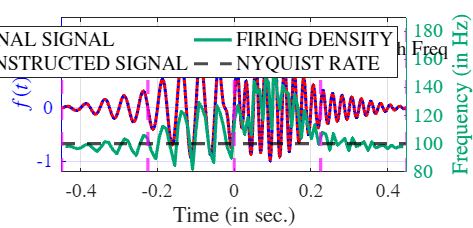



%=== Export as high-quality vector graphic ===
exportgraphics(gcf, 'four_region.pdf', ...
    'ContentType', 'vector', ...
    'BackgroundColor', 'none', ...
    'Resolution', 300);